Das hier ist eigentlich das Training:

tabulate(species)

       Value    Count   Percent
      setosa       50     33.33%
  versicolor       50     33.33%
   virginica       50     33.33%


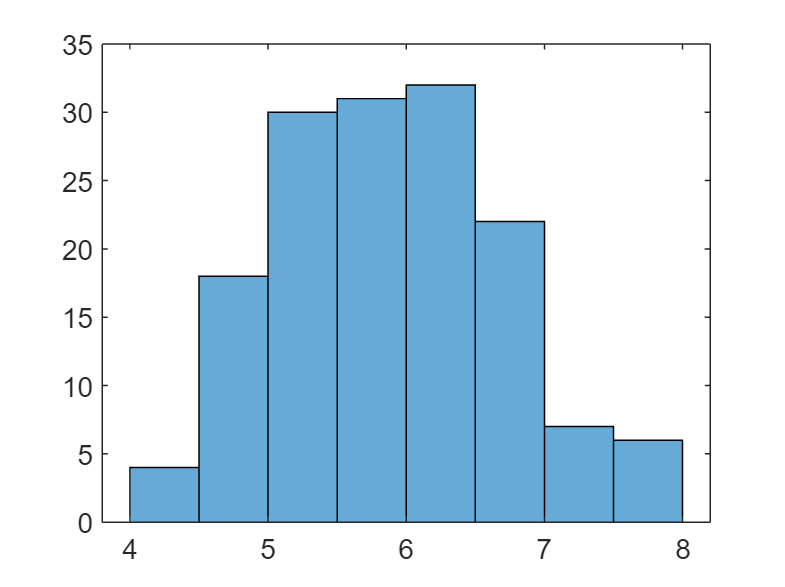

histogram(meas(:,1))

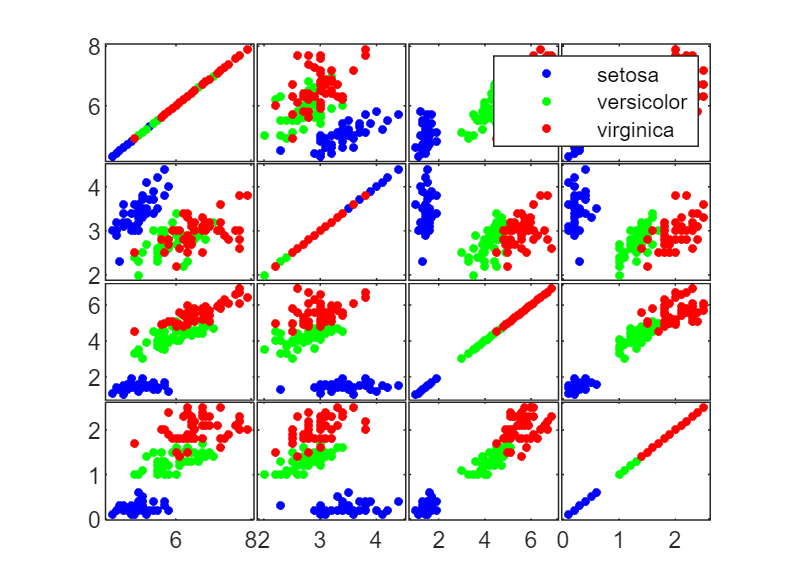

gplotmatrix(meas,meas, species)

iris_baum = fitctree(meas,species)

iris_baum =   ClassificationTree
             ResponseName: 'Y'
    CategoricalPredictors: []
               ClassNames: {'setosa'  'versicolor'  'virginica'}
           ScoreTransform: 'none'
          NumObservations: 150


  Properties, Methods


%view(iris_baum) %korrekt aber unübersichtlich
%view(iris_baum, 'mode','graph') %übersichtlicherer Baum

Jetzt müssen wir die Modelle beurteilen:

resubLoss(iris_baum);%je kleiner desto besser
cv_iris = crossval(iris_baum)%beurteilt das Modell nach Qualität

cv_iris =   ClassificationPartitionedModel
    CrossValidatedModel: 'Tree'
         PredictorNames: {'x1'  'x2'  'x3'  'x4'}
           ResponseName: 'Y'
        NumObservations: 150
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'setosa'  'versicolor'  'virginica'}
         ScoreTransform: 'none'


  Properties, Methods


kfoldLoss(cv_iris)

ans = 0.0467

iris = [5.9, 3.2, 1.3, 0.25]

iris =     5.9000    3.2000    1.3000    0.2500


predict(iris_baum, iris)

ans = 1×1 cell array
    {'setosa'}


bb_laenge = meas(:,3);
bb_breite = meas(:,4);
bb = table(bb_laenge, bb_breite)

bb = 150×2 table
    bb_laenge    bb_breite
    _________    _________

       1.4          0.2   
       1.4          0.2   
       1.3          0.2   
       1.5          0.2   
       1.4          0.2   
       1.7          0.4   
       1.4          0.3   
       1.5          0.2   
       1.4          0.2   
       1.5          0.1   
       1.5          0.2   
       1.6          0.2   
       1.4          0.1   
       1.1          0.1   
       1.2          0.2   
       1.5          0.4   


nb_model = fitcnb(bb, species, 'ClassNames',{'setosa', 'versicolor','virginica'})%nb= Naive-Bayes

nb_model =   ClassificationNaiveBayes
            PredictorNames: {'bb_laenge'  'bb_breite'}
              ResponseName: 'Y'
     CategoricalPredictors: []
                ClassNames: {'setosa'  'versicolor'  'virginica'}
            ScoreTransform: 'none'
           NumObservations: 150
         DistributionNames: {'normal'  'normal'}
    DistributionParameters: {3×2 cell}


  Properties, Methods



nb_model.DistributionParameters

ans = 3×2 cell array
    {2×1 double}    {2×1 double}
    {2×1 double}    {2×1 double}
    {2×1 double}    {2×1 double}


nb_model.DistributionParameters{2,1}

ans =     4.2600
    0.4699


nb_model.DistributionParameters{:,1}

ans =     1.4620
    0.1737


nb_model.DistributionParameters{1,1}

ans =     1.4620
    0.1737


nb_model.DistributionParameters{3,1}

ans =     5.5520
    0.5519


resubLoss(nb_model)

ans = 0.0400

berechnet = predict(nb_model,bb)

berechnet = 150×1 cell array
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}
    {'setosa'}


confusionmat(species, berechnet)

ans =     50     0     0
     0    47     3
     0     3    47


Mit der confusion Matrix wenden wir unser Modell auf die Messwert an. Wenn das Modell exakt stimmt, sind auf der Spur der Matrix nur 50 zu sehen.

berechnet_baum = predict(iris_baum,meas);
confusionmat(species, berechnet_baum)% Das Baum-Modell war also besser.

ans =     50     0     0
     0    47     3
     0     0    50
